# ECM307-G01T02L03D - Atividade P1

## Atividade P1 - Transformada de Fourier

## Luis Guilherme de Souza Munhoz RA: 20.01937-8 Lab: 3

## Boas Práticas

clc;                                       % limpa a tela
clear all;                                 % limpar as variáveis
close all;                                 % fecha as figuras abertas


## Questão 1.3 - calculando Dn e plotando a reconstrução do sinal

%%%%%%%%%%%%%%%%%%%%%% Questão 1 %%%%%%%%%%%%%%%%%%%%%%
%%% Determinando a transformada de Fourier da onda Triângular do primeiro
%%% item da lista


%% Definindo o sinal triangular - Delta(t), a função gn(t) e inicializando variáveis
    
N = 100;                                % numero de harmônicas


DeltaPositivo = @(t) (t+2);                    % parte crescente
DeltaNegativo = @(t) (-t+2);                   % parte decrescente
gn            = @(n,t,w0) exp(-j*n*w0*t);      % exponencial de Euler
T0            = 4;                             % periodo ex 1
f0            = (1/T0);                        % frequência ex 1
w0            = 2*pi*f0;                       % frequência angular ex 1
n             = [-N:1:N];                      % vetor de harmônicas
f             = n * f0;                        % vetor de frequências para diferentes valores de n
%%% inicializando vetor tempo para visualizar gráficos
Ts            = T0 * 10^(-3);                      % passo do vetor tempo
tempo         = [-T0/2:Ts:T0/2];                % Vetor tempo para visualização do sinal

%%% Determinação do coeficiente Dn pela integral do Dn
syms t
DnQ1          = inv(T0)*(int((DeltaPositivo)*gn(1,t,w0),t,-(T0)/2,0)+int((DeltaNegativo)*gn(1,t,w0),t,0,(T0)/2));
%%%%%%%%%% pode-se ver que a o resultado para n = 1 é igual ao resultado
%%%%%%%%%% obtido analiticamente
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% Calculando Dn da mesma forma utilizada para calculá-lo analiticamente
syms w0
DeltaWQ1 = (int(((DeltaPositivo))*gn(1,t,w0),t,-(T0)/2,0)+int(((DeltaNegativo))*gn(1,t,w0),t,0,(T0)/2));
w0 = 2*pi/T0;
Dn1      = eval(DeltaWQ1)/T0

Dn1 = 0.4053

DnReal        = eval(DnQ1)

DnReal = 0.4053

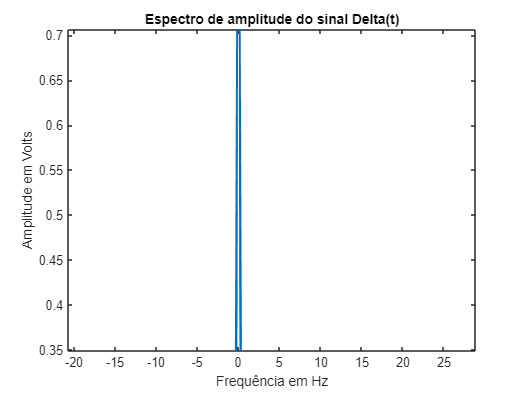

%%%%%%%%% pode-se ver que obtivemos o mesmo resultado
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%% Determinando o termo Dn simbolicamente

syms n t

Dn = (1/T0)*(int(DeltaPositivo*gn(n,t,w0),t,-T0/2,0) + int(DeltaNegativo*gn(n,t,w0),t,0,T0/2));
Dn0 = (1/T0)*(int(DeltaPositivo,t,-T0/2,0) + int(DeltaNegativo,t,0,T0/2));

%% Determinando o termo Dn numericamente

n=[-N:1:N];
 
Dn = eval(Dn);
Dn0 = eval(Dn0);      % tirando do domínio simbólico
Dn(N+1) = Dn0;        % Subistituindo Dn0 vetor Dn

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% plotando espectro de amplitude do sinal
figure(1) 
plot(f,abs(Dn),"linewidth", 2);                         % Na frequência o sinal é discreto
title('Espectro de amplitude do sinal Delta(t)');
xlabel('Frequência em Hz');
ylabel('Amplitude em Volts');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
pk = 0;
for k = 0 : 2*N   

  pk = pk + Dn(k+1)*exp(j*n(k+1)*w0*tempo);  % sem deslocamento no tempo

end
%%% Plotando Delta(t)
figure(2)
plot(tempo,pk,"linewidth", 3)

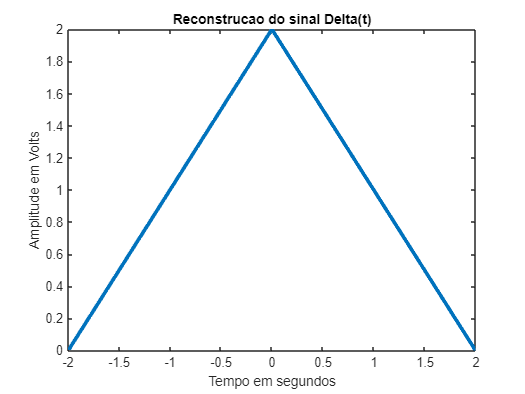

title('Reconstrucao do sinal Delta(t)');
xlabel('Tempo em segundos');
ylabel('Amplitude em Volts');

## Questao 1.4 - Cálculo do número de harmônicas necessário para 95% da potência do sinal

%% Determinando a potência do sinal g(t)
Pg = inv(T0)*int((t+2)^2,t,-2,0)+inv(T0)*int((-t+2)^2,t,0,2);
Pg = eval(Pg)

Pg = 1.3333

%%% Verificando a potência por meio do percentual entre a soma cumulativa dos elementos do
%%% vetor Dn e o Pg

%%  o módulo do Dn_Negativo é igual ao módulo de Dn
%%  portanto, usa-se 2 * abs(Dn) no cálculo

PN = cumsum([1*Dn(N+1)^2,  2*abs(Dn(N+2:end)).^2]); %% Acumula os valores elemento a elemento

for k = 0:2*N
    Pk = PN(k+1);
    percentual = Pk/Pg;
    if(percentual >= 0.95)
        disp(percentual)
        disp(fprintf("assim o n necessário é n = %i", k+1))
        break;
    end
end

    0.9964



assim o n necessário é n = 2    28



## Questão 2.3 - calculando Dn e plotando a reconstrução do sinal

T0     = 8;                             % periodo ex 1
f0     = (1/T0);                        % frequência ex 1
w0     = 2*pi*f0;                       % frequência angular ex 1
n      = [-N:1:N];                      % vetor de harmônicas
f      = n * f0;                        % vetor de frequências para diferentes valores de n
%%%%%% Calculando Dn e comparando com o analítico
%%% Determinação do coeficiente Dn pela integral do Dn
syms t
Dn1_Q2 = DnQ1*(exp(-j*1*w0*2)-exp(-j*1*w0*6));  % com deslocamento no tempo
Dn1_RealQ2 = eval(Dn1_Q2)

Dn1_RealQ2 = 0.0000 - 0.8106i

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% Calculando Dn da mesma forma utilizada para calculá-lo analiticamente
DeltaW     = DeltaWQ1*(exp(-j*1*w0*2)-exp(-j*1*w0*6));  % com deslocamento no tempo
Dn1RealQ2  = eval(DeltaW)/T0

Dn1RealQ2 = 0.0000 - 0.8106i



%%% calculando Dn1 pela integral obtida analiticamente
DeltaWQ2 = 32/(pi^2)*(exp(-j*pi/2)-exp(-j*3*pi/2))

DeltaWQ2 = 0.0000 - 6.4846i

DnAnalitico = DeltaWQ2/T0

DnAnalitico = 0.0000 - 0.8106i

%%%%%%%%% como previsto, o Dn deslocado só tem parte imaginária e bate é
%%%%%%%%% igual ao calculado analiticamente
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%% inicializando vetor tempo para visualizar gráficos
Ts     = T0 * 10^(-3);                  % passo do vetor tempo
tempo  = [0:Ts:T0];                     % Vetor tempo para visualização do sinal

%% Determinando Delta(t-2) - Delta(t-6) de forma estruturada 

syms n t

n  = [-N:1:N];
pk = 0;
for k = 0 : 2*N   
%%%% utilizando Dn do exercicio anterior
  
  Delta2 = Dn(k+1)*exp(-j*n(k+1)*w0*2);
  Delta6 = -Dn(k+1)*exp(-j*n(k+1)*w0*6);
  soma = Delta2 + Delta6;
  DnQ2 = soma*exp(j*n(k+1)*w0*tempo);
  pk = pk + soma*exp(j*n(k+1)*w0*tempo);
end
%%% plotando Delta(t-2) - Delta(t-6)
figure(3)
plot(tempo, pk,"linewidth", 3)

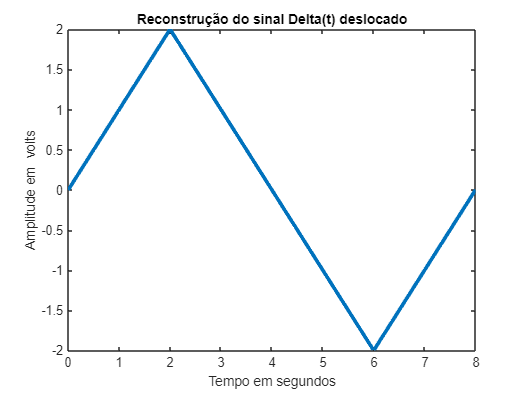

title('Reconstrução do sinal Delta(t) deslocado');
xlabel('Tempo em segundos');
ylabel('Amplitude em  volts')

## Questão 2.4 - Cálculo do número de harmônicas necessário para 95% da potência do sinal

%% Determinando a potência do sinal g(t)
Pg = inv(T0)*(int((t)^2,t,0,2)+int((-t+4)^2,t,2,4) - (int((t-4)^2,t,4,6)+int((-t+8)^2,t,6,8)));
Pg = eval(Pg)

Pg = 0

%%% Verificando a potência por meio do percentual entre a soma cumulativa dos elementos do
%%% vetor Dn e o Pg

%%  o módulo do Dn_Negativo é igual ao módulo de Dn
%%  portanto, usa-se 2 * abs(Dn) no cálculo
%%% help cumsum
%%% cumsum Cumulative sum of elements.
PN = cumsum([1*DnQ2(N+1)^2,  2*abs(DnQ2(N+2:end)).^2]); %% Acumula os valores elemento a elemento

for k = 0:2*N
    Pk = PN(k+1);
    percentual = Pk/Pg;
    if(percentual >= 0.95)
        disp(fprintf("assim o n necessário é n = %i", k+1))
        break;
    end
end

assim o n necessário é n = 1    28

